# **Apoyo en el desarrollo del Proyecto de Grado MIACON**

[MÓDULO 2: Identificación y control de una planta de primer orden](https://sites.google.com/view/miacon-proyectodegrado/gu%C3%ADas-de-laboratorio/m%C3%B3dulo-2-identificaci%C3%B3n-y-control-de-una-planta-de-primer-orden)

- `Hecho por:`` Diego Andrés García Díaz.`

- `Código:`` 2195533.`

- `Fecha:`` 26/09/2025.`

- `Asignatura:`` Control II (Adelanto de Nota).`

## Módelo para un Sitema Térmico (Primer Orden)

### $G_P \left(\mathcal{s}\right)=\frac{K_p }{T_{\textrm{p1}} \cdot \mathcal{s}+1}\cdot e^{-T_d \cdot \mathcal{s}}$;

### $G_P \left(\mathcal{s}\right)=\textrm{Actuador}+\textrm{Planta}+\textrm{Sensor}$;

### $K=K_p =\textrm{Ganancia}$; 

$K=\frac{\Delta Y\;\left(\textrm{salida}\right)}{\Delta U\;\left(\textrm{entrada}\right)}$**;**

### ${T=\;T}_{\textrm{p1}} =\textrm{Constante}\;\textrm{de}\;\textrm{tiempo}$; 

$T=\frac{3}{2}\left(t_2 -t_1 \right)$**;**

### ${L=\;T}_d =\textrm{Tiempo}\;\textrm{muerto}\;\left(\textrm{Delay}\right)$ ;


$$L=t_2 -T$$


## Modelo identificado siguiendo las instrucciones de la página web:

## 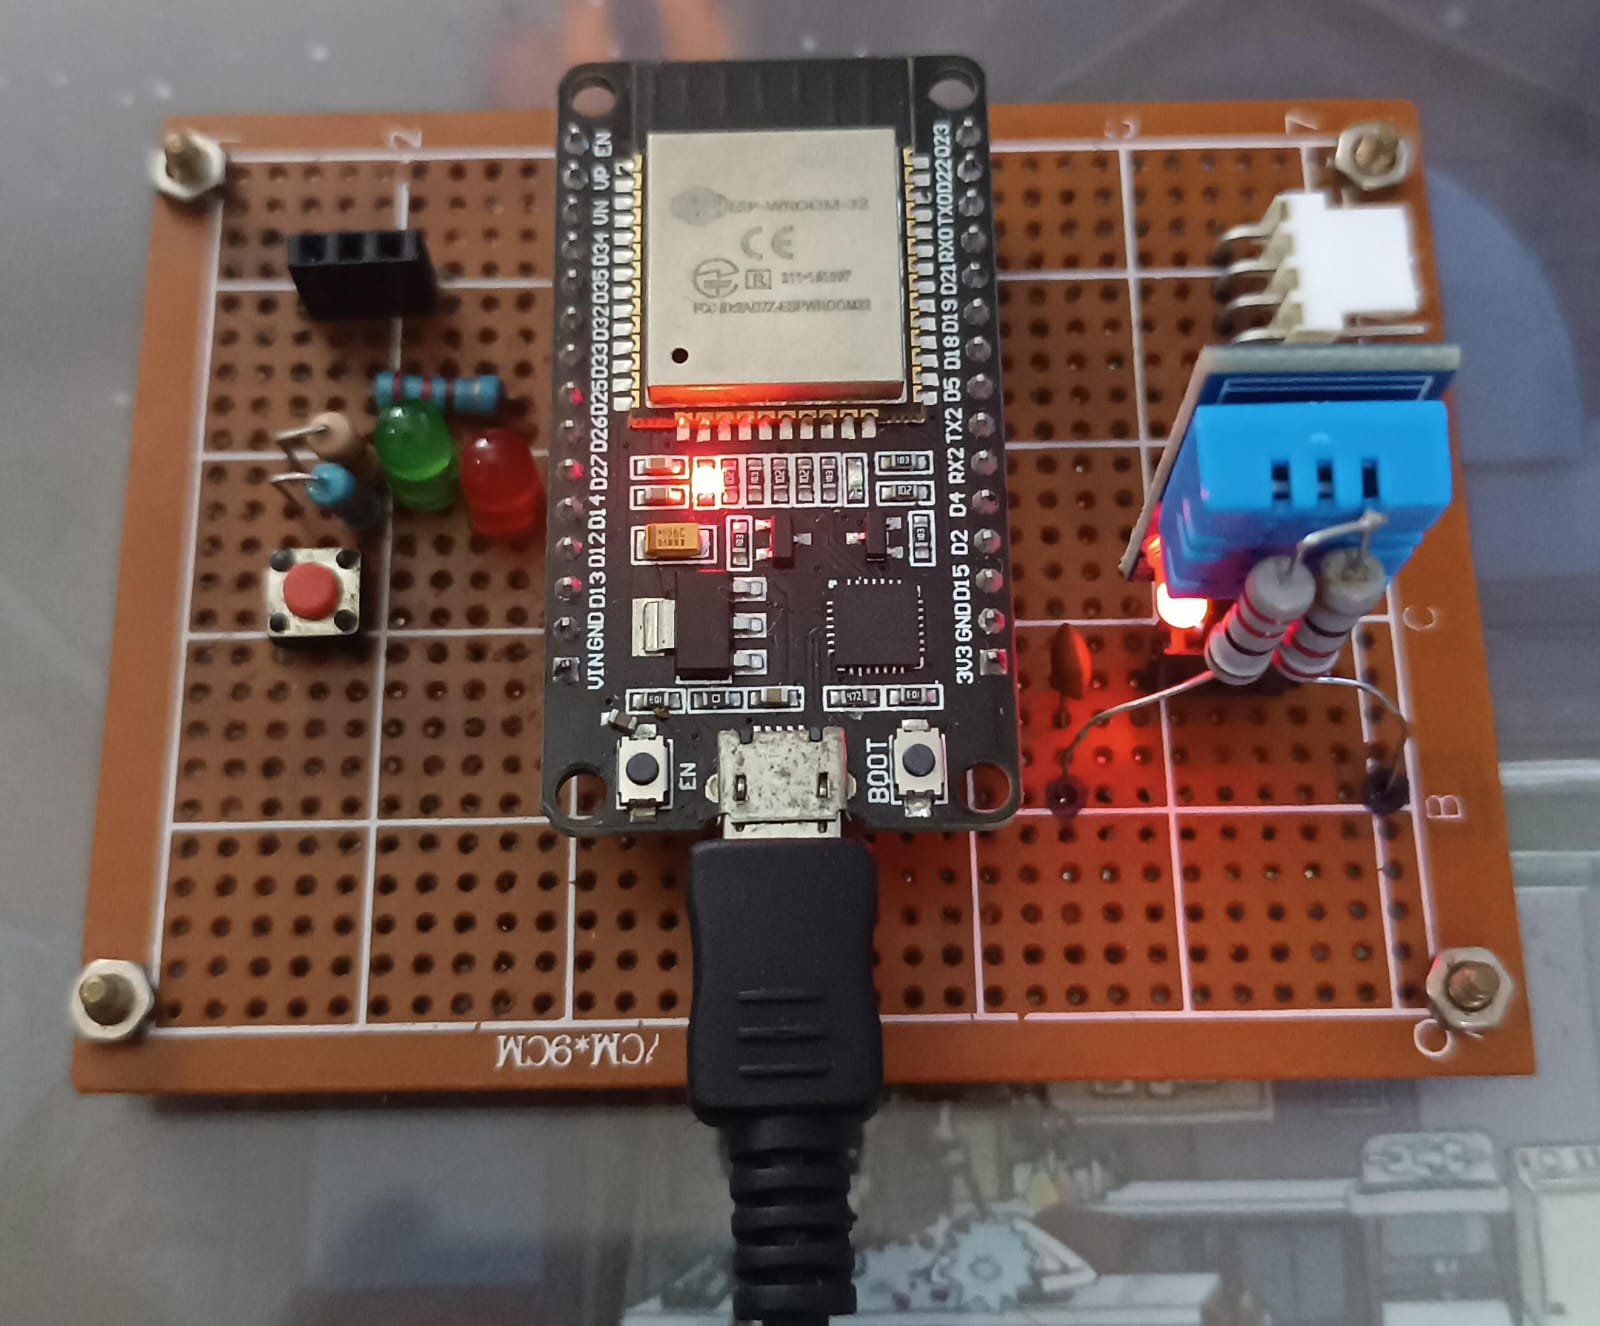

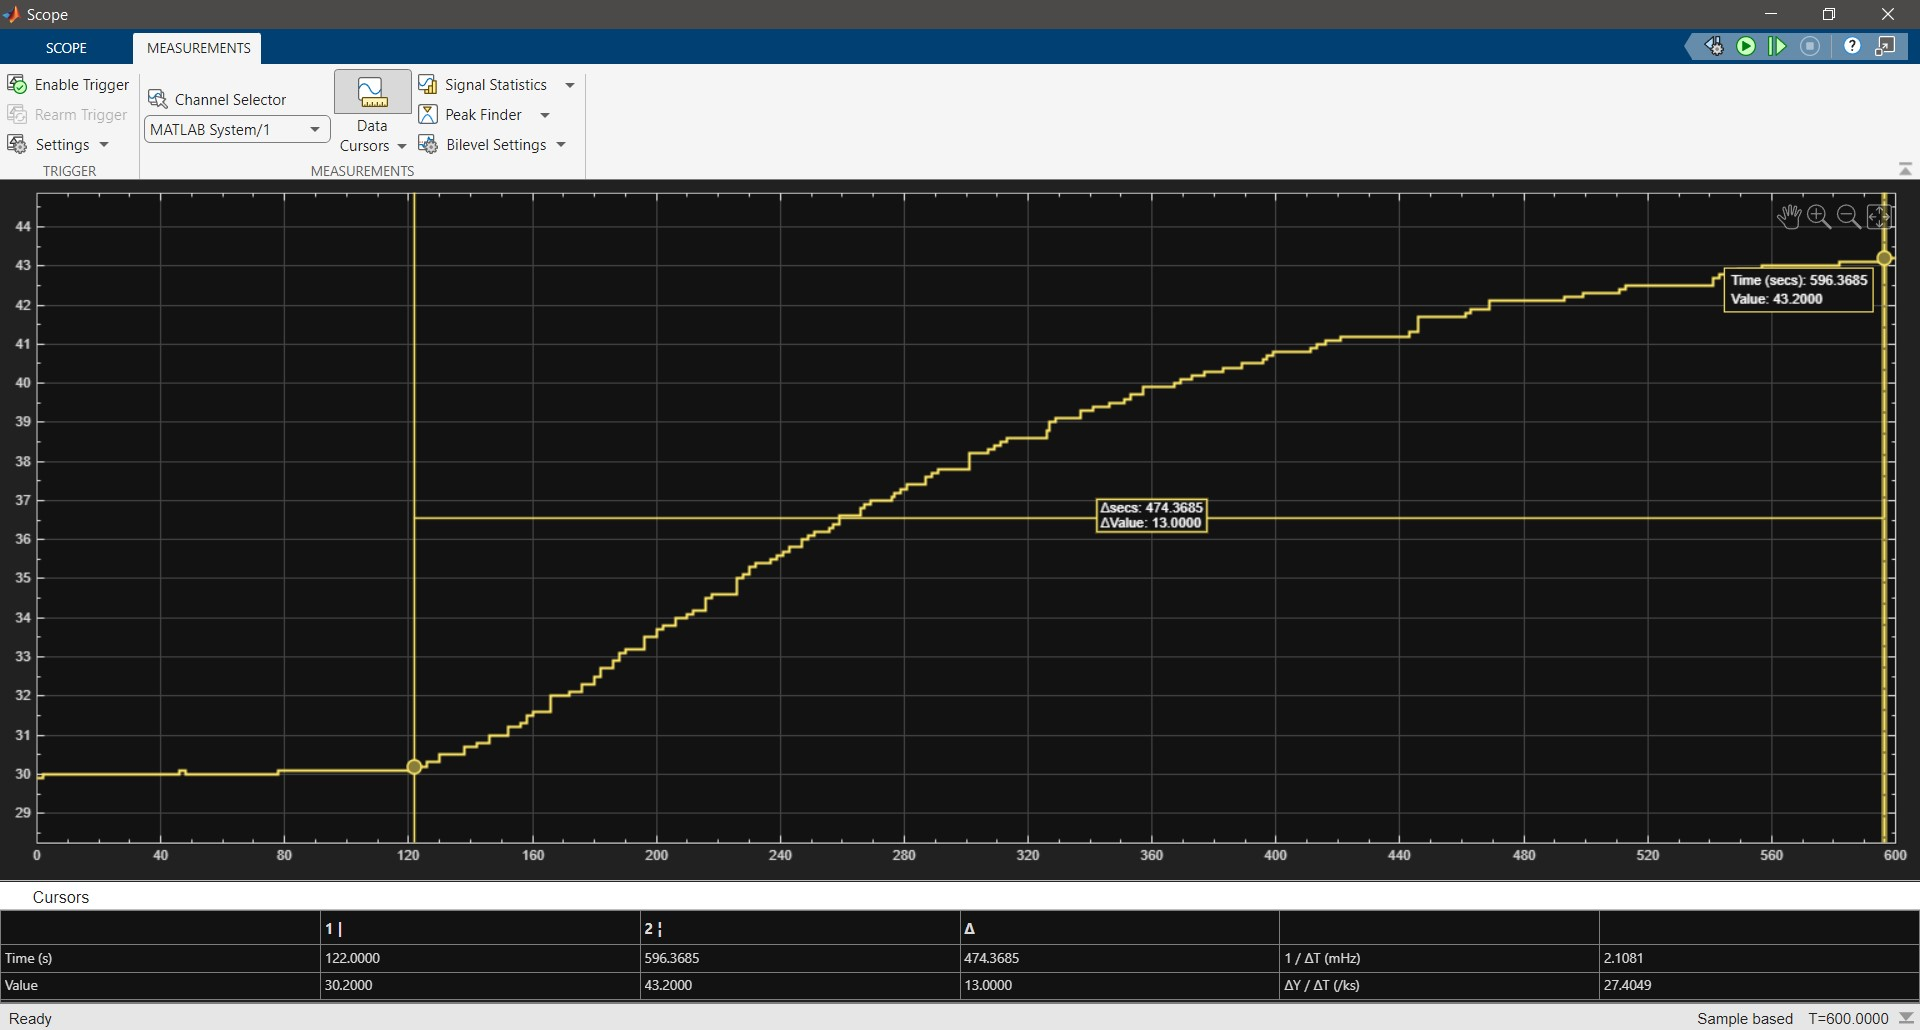

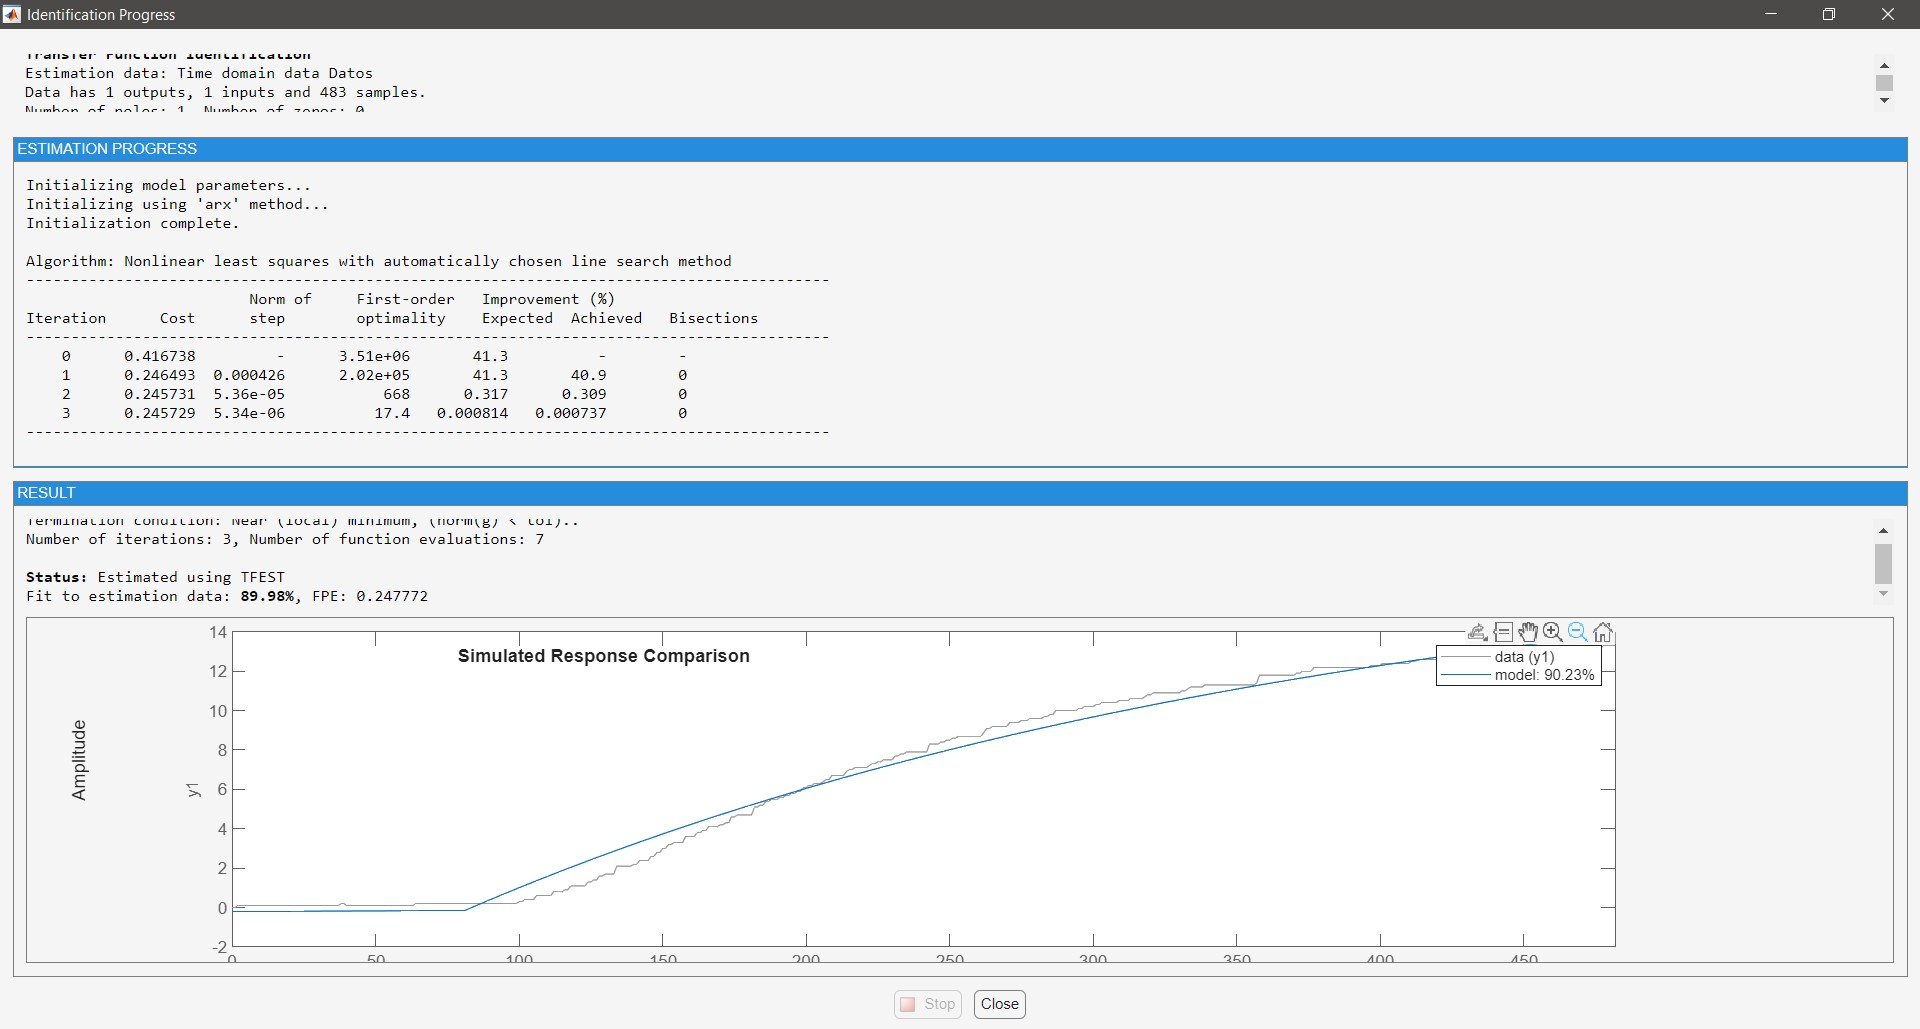

## 
$${\mathrm{P1D}\;\;\;\to \;\;\;G}_{P_1 } \left(\mathcal{s}\right)=P\left(\mathcal{s}\right)=\frac{0\ldotp 11864}{170\ldotp 65\cdot \mathcal{s}+1}\cdot e^{-30\cdot \mathcal{s}}$$


### `Ajuste de 90.23% > 80%`

### **Validación en Simulink:**

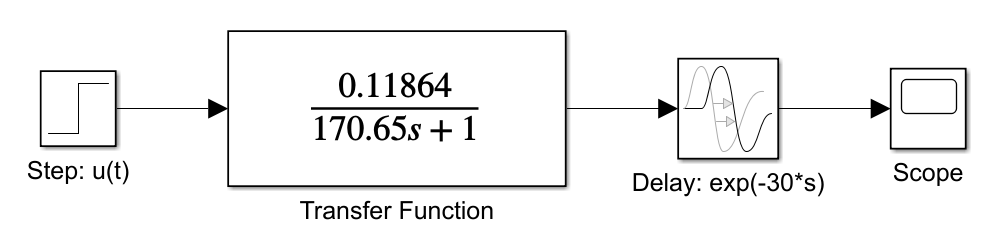

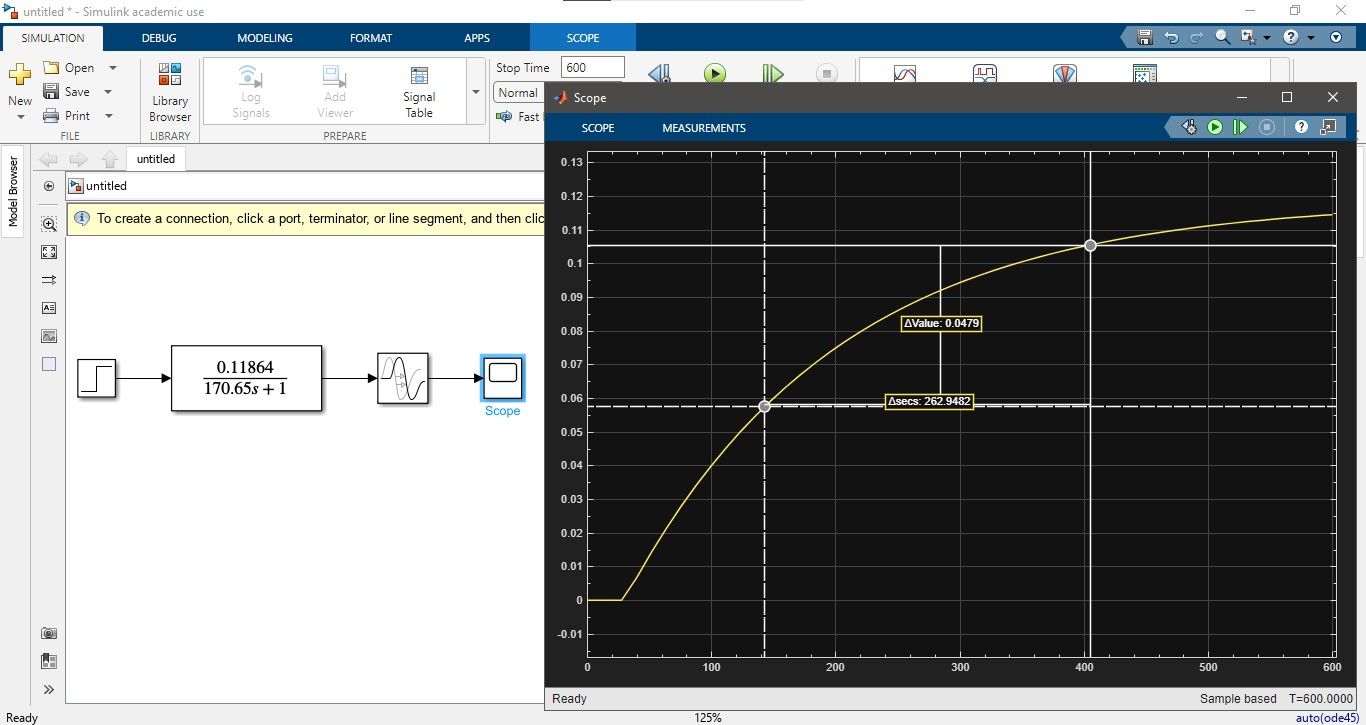

## 
$$G_P \left(\mathcal{s}\right)=\frac{0\ldotp 1144}{158\ldotp 7423\cdot \mathcal{s}+1}\cdot e^{-31\ldotp 7485\cdot \mathcal{s}}$$


#### $t_1 =L+\frac{1}{3}\cdot T=84\ldotp 6626\;\left\lbrack s\right\rbrack$**; **$t_2 =L+T=190\ldotp 4908\;\left\lbrack s\right\rbrack$** ;**

#### $\mathrm{Ganancia}\;\;\to \;\;\;K=\frac{\Delta Y\;\left(\mathrm{salida}\right)}{\Delta U\;\left(\mathrm{entrada}\right)}=0\ldotp 1144$**; **

#### $\mathrm{Constante}\;\mathrm{de}\;\mathrm{tiempo}\;\;\to \;\;\;T=\frac{3}{2}\left(t_2 -t_1 \right)=158\ldotp 7423\;\left\lbrack s\right\rbrack$**; **

#### 
$$\mathrm{Retardo}\;\;\to \;\;\;L=t_2 -T=31\ldotp 7485\;\left\lbrack s\right\rbrack$$


### **A continuación se presenta el desarrollo para el respectivo deseño de los controladores P, PI, PD y PID:**

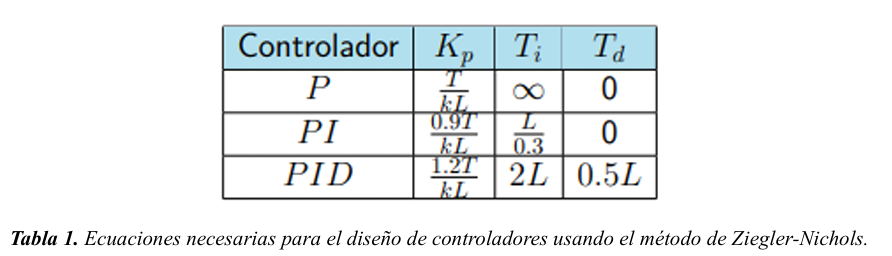

#### 
$$\mathrm{Funciona}\;\mathrm{mejor}\;\mathrm{cuando}\;\;\to \;\;\;0\ldotp 1<\frac{L}{T}<0\ldotp 6$$


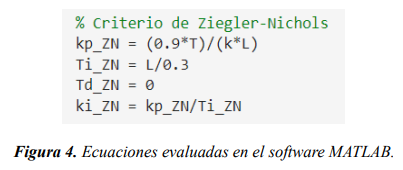

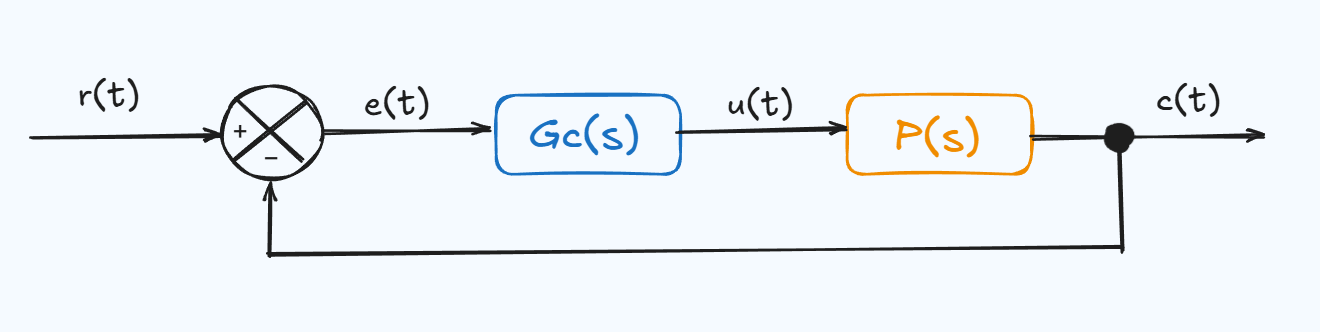

#### 
$$G_{\mathrm{LC}} \left(\mathcal{s}\right)=\frac{C\left(\mathcal{s}\right)}{R\left(\mathcal{s}\right)}=\frac{G_C \left(\mathcal{s}\right)\cdot P\left(\mathcal{s}\right)}{1+G_C \left(\mathcal{s}\right)\cdot P\left(\mathcal{s}\right)}\approx \frac{\omega_n^2 }{{\mathcal{s}}^2 +2\cdot \zeta \cdot \omega_n \cdot \mathcal{s}+\omega_n^2 }$$



$$G_C \left(\mathcal{s}\right)=\frac{U\left(\mathcal{s}\right)}{E\left(\mathcal{s}\right)}=K\frac{\left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)}{\left(\mathcal{s}+p_1 \right)\cdot \left(\mathcal{s}+p_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+p_n \right)}\;\;\to \;\;\mathrm{Función}\;\mathrm{de}\;\mathrm{Transferencia}\;\mathrm{del}\;\mathrm{Controlador}\;\mathrm{Generalizada}$$



$$P\left(\mathcal{s}\right)=\frac{N\left(\mathcal{s}\right)}{D\left(\mathcal{s}\right)}\;\;\to \;\;\mathrm{Función}\;\mathrm{de}\;\mathrm{Transferencia}\;\mathrm{del}\;\mathrm{Sistema}\;o\;\mathrm{Planta}$$



$$G_{\mathrm{LC}} \left(\mathcal{s}\right)=\frac{C\left(\mathcal{s}\right)}{R\left(\mathcal{s}\right)}=\frac{K\frac{\left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)}{\left(\mathcal{s}+p_1 \right)\cdot \left(\mathcal{s}+p_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+p_n \right)}\cdot \frac{N\left(\mathcal{s}\right)}{D\left(\mathcal{s}\right)}\;\;}{1+K\frac{\left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)}{\left(\mathcal{s}+p_1 \right)\cdot \left(\mathcal{s}+p_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+p_n \right)}\cdot \frac{N\left(\mathcal{s}\right)}{D\left(\mathcal{s}\right)}\;\;}$$


#### 
$$G_{\mathrm{LC}} \left(\mathcal{s}\right)=\frac{K\cdot \left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)\cdot N\left(\mathcal{s}\right)\;\;}{\left(\mathcal{s}+p_1 \right)\cdot \left(\mathcal{s}+p_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+p_n \right)\cdot D\left(\mathcal{s}\right)+K\cdot \left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)\cdot N\left(\mathcal{s}\right)}$$



$$\frac{K\cdot \left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)\cdot N\left(\mathcal{s}\right)\;\;}{\left(\mathcal{s}+p_1 \right)\cdot \left(\mathcal{s}+p_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+p_n \right)\cdot D\left(\mathcal{s}\right)+K\cdot \left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)\cdot N\left(\mathcal{s}\right)}\approx \frac{\omega_n^2 }{{\mathcal{s}}^2 +2\cdot \zeta \cdot \omega_n \cdot \mathcal{s}+\omega_n^2 }$$


% Hecho por: Diego Andrés García Díaz.
% Código: 2195533.
% Fecha: 24/09/2025.
% Asignatura: Control II (Adelanto de Nota).
% 
% ------------------------------------------------------------------------------
% -------------- Diseño Controladores para Control de Temperatura --------------
% ------------------------------------------------------------------------------


% Criterio de Ziegler-NicholsS
kp_ZN = (0.9*T)/(k*L)
Ti_ZN = L/0.3
Td_ZN = 0
ki_ZN = kp_ZN/Ti_ZN







% ------------------------------------------------------------------------------
